# **[2021-21674 : Kwon Joonwoo] - Midterm Answer**

## **Q1. Focusing with amplitude modulation**

### ◆ Calculation of PSF

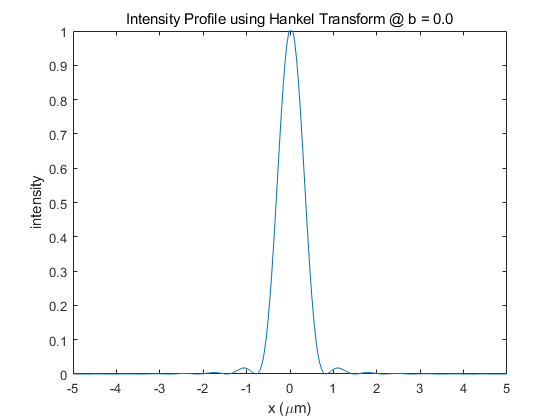

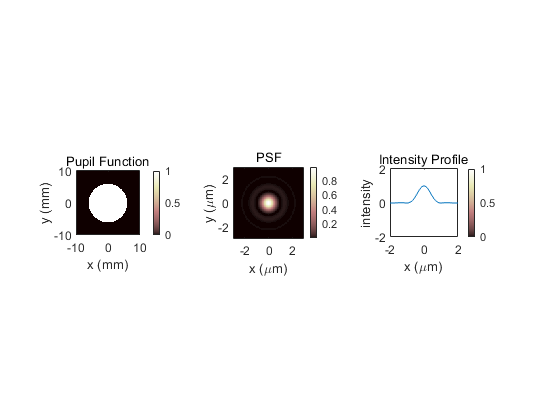

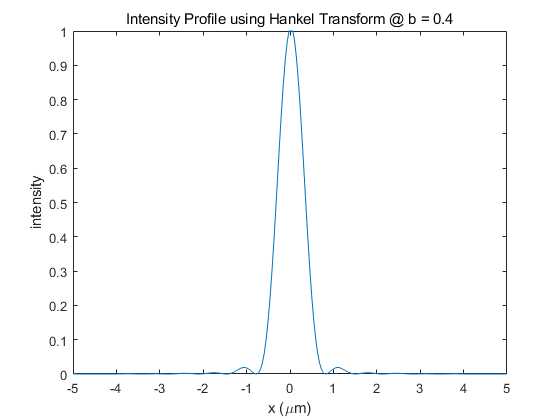

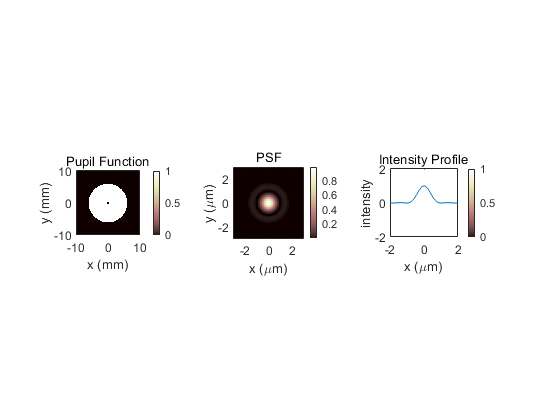

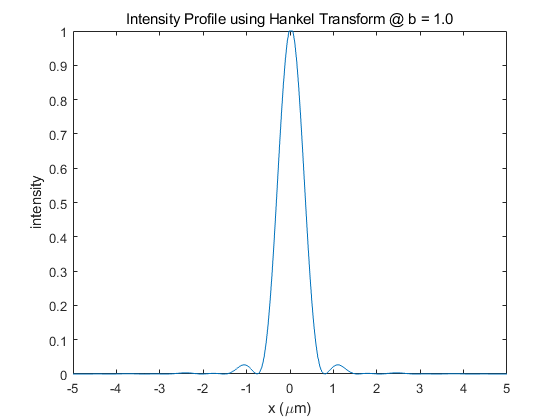

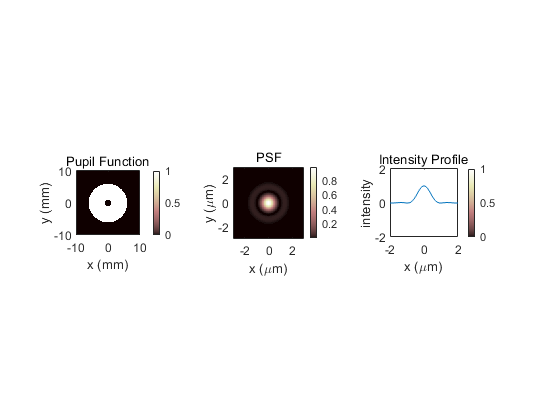

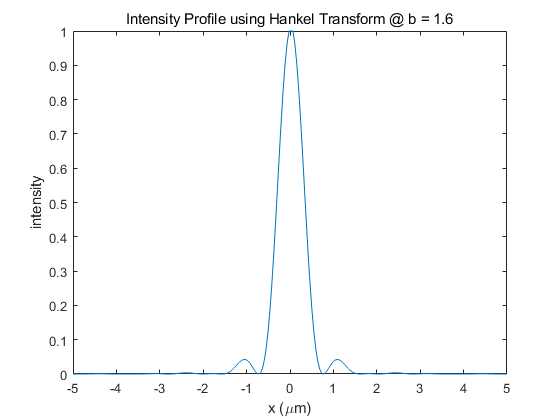

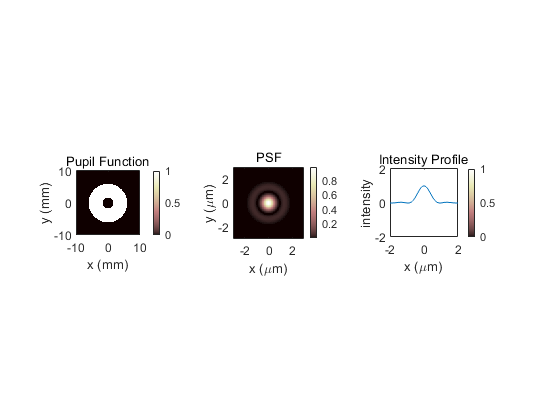

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%               Finding PSF using Hankel Transform              %%%%%%%%%%%%%% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all;
clear;
clc;

% parameters
lambda = 0.0005;    % mm, in vacuum
k = 2*pi/lambda;    % vacuum wavenumber

a = 6;              % mm, circular aperture radius
f = 20;             % mm, focal length
xL = a*15;          % mm, half limit in x
yL = a*15;          % mm, half limit in y
Nx = 1024*4;
Ny = 1024*4;

% Coordinate 1
xp = linspace(-xL,xL,Nx);  % 1D vector
yp = linspace(-yL,yL,Ny);  % 1D vector
[x, y] = meshgrid(xp,yp); 
r = sqrt(x.^2 + y.^2);

% Coordinate 2
fx = 1/diff(xp(1:2))*linspace(-Nx/2,Nx/2-1,Nx)/Nx;
fy = 1/diff(yp(1:2))*linspace(-Ny/2,Ny/2-1,Nx)/Ny;
x2 = fx*(lambda*(f));
y2 = fy*(lambda*(f));
[x2D, y2D] = meshgrid(x2,y2);
rho = sqrt(x2D.^2 + y2D.^2);

%
Nb = 30;
bs = linspace(0,5.9,Nb);

xLdisp = 3;   % micron
yLdisp = 3;   % micron

analyze_bs = zeros(Nb, Nx);

for cnt = 1:length(bs)
    b = bs(cnt);
    n_r2D = (k*a/f)*rho;
    n2_r2D = (k*b/f)*rho;
    
    % Pupil Function
    Pupil_h = zeros(size(r));
    Pupil_h(r>b & r<a) = 1;
    
    if b ~= 0
        apsf = 2/(a^2-b^2)*(a^2*besselj(1,n_r2D)./(n_r2D) - b^2*besselj(1,n2_r2D)./(n2_r2D));

        ipsf = abs(apsf).^2;
        n_ipsf = ipsf./max(ipsf(:));
        n_ipsf(round(Ny/2)+1, round(Nx/2)+1) = 1; % eliminate NAN value as its value is 1. [ lim(bessel(x)/x) = 0.5 ]
        
        mat = n_ipsf(round(Ny/2)+1,:);
        new_mat = round(mat, 2);
        analyze_bs(cnt,:) = new_mat;
        
        if rem(cnt,3) == 0
            figure; plot(xp, n_ipsf(round(Ny/2)+1,:));
            title(['Intensity Profile using Hankel Transform @ b = ', num2str(b,'% 5.1f')]); xlabel('x (\mum)'); ylabel('intensity');
            xlim([-5 5]);
            
            % subplot - Pupil Function
            figure; subplot(1,3,1); imagesc(xp,yp,Pupil_h); axis image; colormap pink; colorbar;
            set(gca,'YDir','normal','FontSize',9); xlim([-10 10]); ylim([-10 10]);xlabel('x (mm)');ylabel('y (mm)');
            title('Pupil Function');
 
            % subplot - Calculated PSF
            subplot(1,3,2); imagesc(x2*1000,y2*1000,n_ipsf); axis image; colormap pink; colorbar;
            set(gca,'YDir','normal','FontSize',9); xlim([-xLdisp xLdisp]); ylim([-yLdisp yLdisp]); xlabel('x (\mum)'); ylabel('y (\mum)');
            title('PSF');

            % subplot - Intensity Profile
            subplot(1,3,3); plot(x2*1000, mat); axis image; colormap pink; colorbar;
            set(gca,'YDir','normal','FontSize',9); xlim([-2 2]); ylim([-2 2]); xlabel('x (\mum)'); ylabel('intensity');
            title('Intensity Profile');
       
        end
        
    else
        apsf = 2*besselj(1,n_r2D)./(n_r2D);

        ipsf = abs(apsf).^2;
        n_ipsf = ipsf./max(ipsf(:));
        n_ipsf(round(Ny/2)+1, round(Nx/2)+1) = 1; % eliminate NAN value as its value is 1. [ lim(bessel(x)/x) = 0.5 ]
        
        % Intensity Profile
        figure; plot(xp, n_ipsf(round(Ny/2)+1,:));
        title(['Intensity Profile using Hankel Transform @ b = ', num2str(b,'% 5.1f')]); xlabel('x (\mum)'); ylabel('intensity');
        xlim([-5 5]);
        
        % subplot - Pupil Function
        figure; subplot(1,3,1); imagesc(xp,yp,Pupil_h); axis image; colormap pink; colorbar;
        set(gca,'YDir','normal','FontSize',9); xlim([-10 10]); ylim([-10 10]);xlabel('x (mm)');ylabel('y (mm)'); 
        title('Pupil Function');
        
        mat = n_ipsf(round(Ny/2)+1,:);
        new_mat = round(mat, 2);
        analyze_bs(cnt,:) = new_mat;
        
        % subplot - Calculated PSF
        subplot(1,3,2); imagesc(x2*1000,y2*1000,n_ipsf); axis image; colormap pink; colorbar;
        set(gca,'YDir','normal','FontSize',9); xlim([-xLdisp xLdisp]); ylim([-yLdisp yLdisp]); xlabel('x (\mum)'); ylabel('y (\mum)');
        title('PSF');
        
        % subplot - Intensity Profile
        subplot(1,3,3); plot(x2*1000, mat); axis image; colormap pink; colorbar;
        set(gca,'YDir','normal','FontSize',9); xlim([-2 2]); ylim([-2 2]); xlabel('x (\mum)'); ylabel('intensity');
        title('Intensity Profile');
    end
end

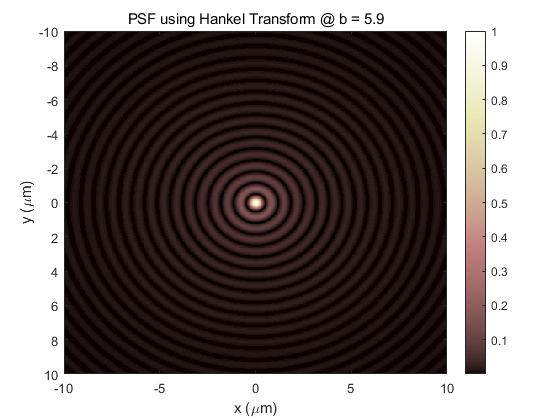


figure; imagesc(xp,yp,n_ipsf);xlim([-10 10]); ylim([-10 10]);
title('PSF using Hankel Transform @ b = 5.9'); colormap('pink'); xlabel('x (\mum)'); ylabel('y (\mum)');
colorbar;

Focus일때 b값을 변화시키면서 PSF를 계산하고 intensity profile을 계산하였다. Annular Aperture 일 때, b값이 증가함에 따라 PSF가 더 좁아지는 것을 볼 수 있다.

PSF가 좁아지므로 따라서 b값이 증가할수록 Resolution이 증가한다. 실제로 psf를 보면 resolution이 더 상승하는 것을 볼 수 있다.

PSF는 Hankel Transform을 통해 구했으며 사용된 수식은 아래와 같다. 또한 r 값이 0일때는 bessel 함수가 $\frac{0}{0}$꼴이 되어 정의가 안되므로 이때는 if-else문을 통해 1 값을 넣어주었다. $\lim_{x\longrightarrow 0} \frac{J_1 \left(x\right)}{x}=0\ldotp 5$ 

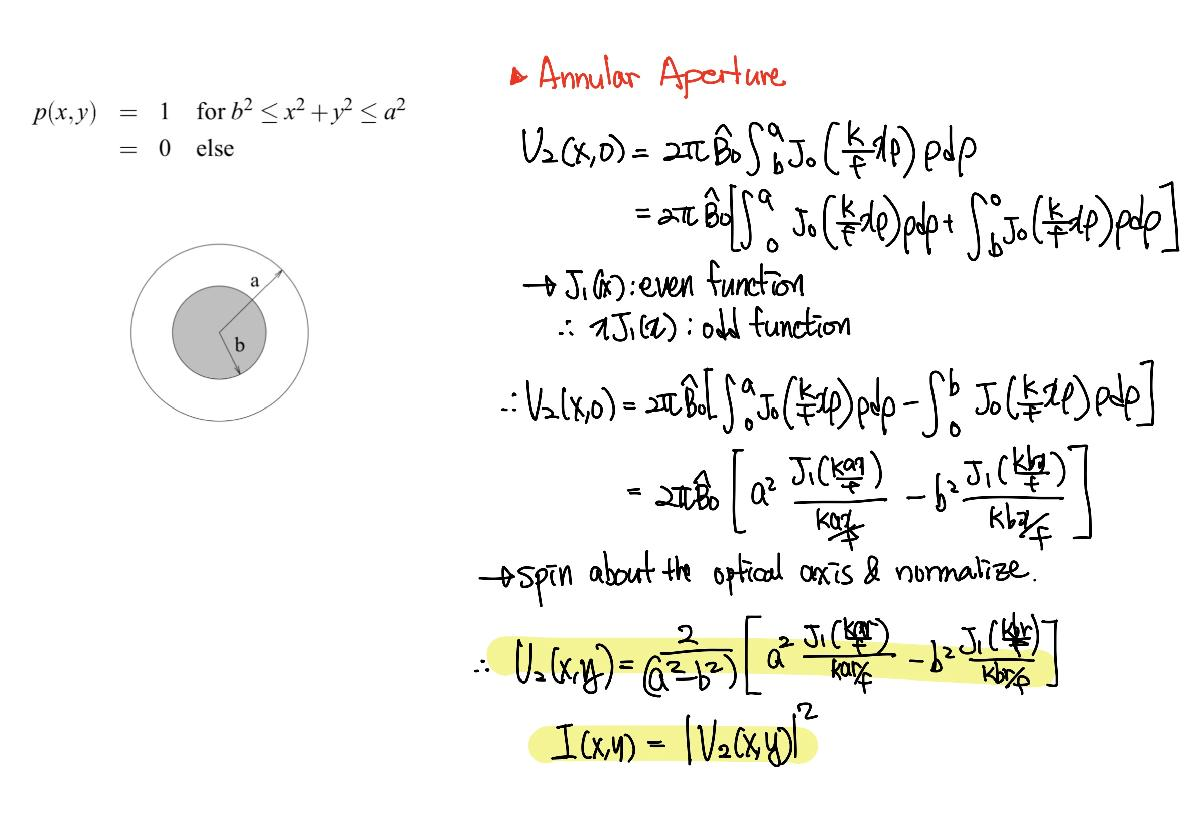

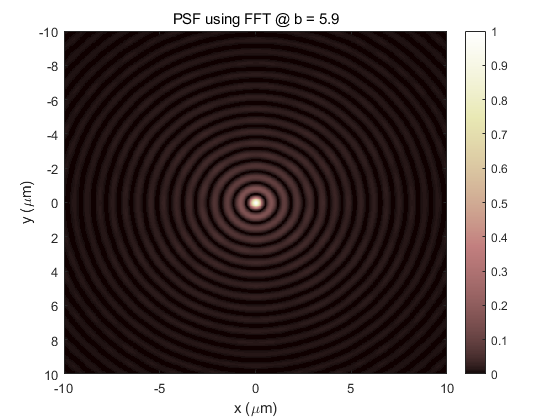


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%        Finding PSF using Fast Fourier Transform (FFT)         %%%%%%%%%%%%%% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% Calculation of PSF 
analyze_bs_fft = zeros(Nb, Nx);

for cnt = 1:length(bs)
    b = bs(cnt);
    
    % Pupil Function
    Pupil = zeros(size(r));
    Pupil(r>b & r<a) = 1;
    
    % PSF
    psf_fft = fftshift(fft2(Pupil));
    ipsf_fft = abs(psf_fft).^2;
    n_ipsf_fft = ipsf_fft./max(ipsf_fft(:));
    
    % Intensity Profile @ y=0
    mat_fft = n_ipsf_fft(round(Ny/2)+1,:);
    new_mat_fft = round(mat_fft, 2);
    analyze_bs_fft(cnt,:) = new_mat_fft; 
end

figure; imagesc(xp,yp,n_ipsf_fft);xlim([-10 10]); ylim([-10 10]);
title('PSF using FFT @ b = 5.9'); colormap('pink'); xlabel('x (\mum)'); ylabel('y (\mum)');
colorbar;

다음으로 Fast Fourier Transform을 이용하여 PSF를 구해보았다. 2D 평면에서 봤을때 Hankel Transform을 이용한 PSF와 FFT를 사용하여 구한 PSF는 얼추 비슷한 것을 볼 수 있다.

### ◆ Finding FWHM

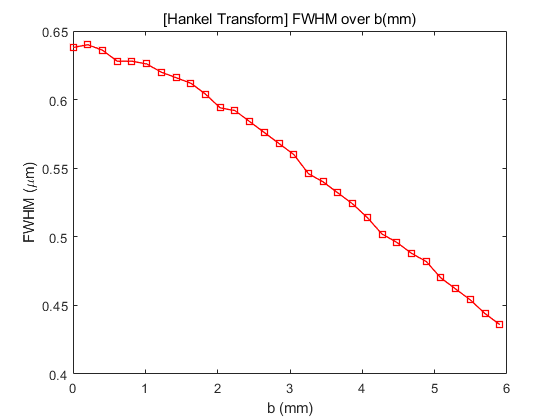


%% Calculation of FWHM (Hankel Transform)

FWHM_bs = zeros(1, Nb);
for cnt = 1:Nb
    xx = -xL:0.001:xL;
    yy = interp1(xp, analyze_bs(cnt,:),xx,'spline');
    newt_yy = round(yy,2);
    zero_mat = 0.5*ones(size(newt_yy));
    real_new = abs(newt_yy-zero_mat);
    rlocation = find(real_new==min(real_new));
    final_loc = abs(xx(rlocation)); 
    FWHM_bs(:,cnt) = min(final_loc)*2; %% pick the smallest location among calculated FWHMs 
end

bxx = 1:3:length(FWHM_bs);

temp_FWHM_bs = zeros(size(bxx));
for k = 1:length(bxx)
    temp_FWHM_bs(:,k) = FWHM_bs(bxx(k)); 
end

bs = linspace(0,5.9,Nb);
sq = 0:(0.01):(Nb);
new_FWHM_bs = interp1(bxx, temp_FWHM_bs, sq,'spline');

figure; plot(bs, FWHM_bs,'-rs', 'LineWidth', 1);
title('[Hankel Transform] FWHM over b(mm)');
xlabel('b (mm)');ylabel('FWHM (\mum)'); 

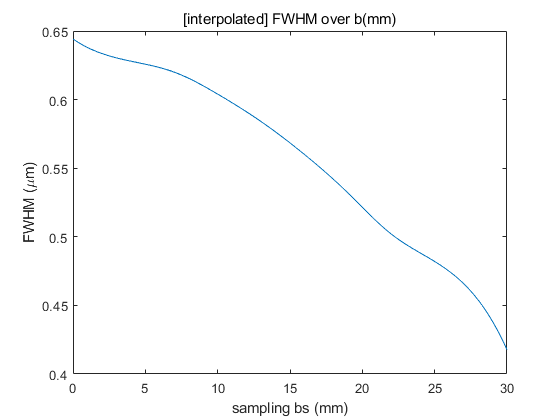

figure; plot(sq, new_FWHM_bs, 'LineWidth', 1); 
title('[interpolated] FWHM over b(mm)');
xlabel('sampling bs (mm)');ylabel('FWHM (\mum)'); 

다음은 FWHM을 구해보겠다. FWHM을 구하기 위해선 Intensity가 0.5가 되는 지점을 찾아야 하는데 기존의 sampling points로는 정확한 지점을 찾을 수 없다.

따라서 interpolation을 통해 각 sampling point 사이에 점들을 더 추가해서 더 촘촘하게 값을 찾아보겠다. spline interpolation을 이용했으며 이를 통해 intensity가 0.5인 지점을 찾았다.

이때 rounding problem (부동소수점) 문제 때문에 intensity가 0.5를 만족하는 지점이 단 두곳이 나오는 것이 아니라 여러 곳이 나올 수도 있는데 이런 경우, FWHM이 가장 작게 만들어지는 X값을 선택하였다.

이는 소수점 계산의 한계로 인해 생기는 오차라고 할 수 있겠다. 따라서 Hankel transform을 통해 구한 FWHM 값을 빨간색으로 Plot하고 이 그래프를 다시 한 번 spline interpolation 해서 파란색 graph로 plot 했다.

그래프를 보면 b 값이 증가할수록 FWHM이 줄어드는 것을 볼 수 있다.

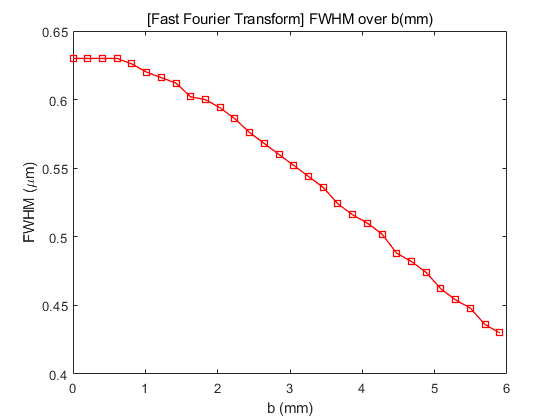


%% Calculation of FWHM (FFT)

FWHM_bs_fft = zeros(1, Nb);
for cnt = 1:Nb
    xx = -xL:0.001:xL;
    yy_fft = interp1(xp, analyze_bs_fft(cnt,:),xx,'spline');
    newt_yy_fft = round(yy_fft,2);
    zero_mat_fft = 0.5*ones(size(newt_yy_fft));
    real_new_fft = abs(newt_yy_fft-zero_mat_fft);
    rlocation_fft = find(real_new_fft==min(real_new_fft));
    final_loc_fft = abs(xx(rlocation_fft)); 
    FWHM_bs_fft(:,cnt) = min(final_loc_fft)*2; %% pick the smallest location among calculated FWHMs 
end

bxx_fft = 1:3:length(FWHM_bs_fft);

temp_FWHM_bs_fft = zeros(size(bxx_fft));
for k = 1:length(bxx_fft)
    temp_FWHM_bs_fft(:,k) = FWHM_bs_fft(bxx(k)); 
end

bs = linspace(0,5.9,Nb);
sq_fft = 0:(0.01):(Nb);
new_FWHM_bs_fft = interp1(bxx, temp_FWHM_bs_fft, sq_fft,'spline');

figure; plot(bs, FWHM_bs_fft,'-rs', 'LineWidth', 1);
title('[Fast Fourier Transform] FWHM over b(mm)');
xlabel('b (mm)');ylabel('FWHM (\mum)'); 

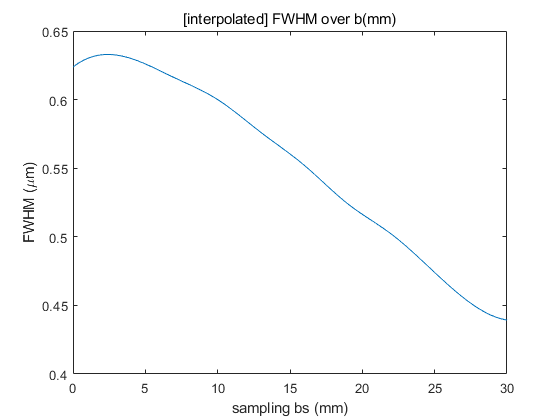

figure; plot(sq_fft, new_FWHM_bs_fft, 'LineWidth', 1); 
title('[interpolated] FWHM over b(mm)');
xlabel('sampling bs (mm)');ylabel('FWHM (\mum)'); 

또한 FFT를 이용하여 FWHM을 구하고 이 그래프를 Spline interpolate 하였다. 위와 똑같은 방식으로 FWHM을 구했다.

### ◆ Comparison of FWHM improvement between $\frac{b}{a}=0\ldotp 8$ and $\frac{b}{a}=0$ 

%%%% Hankel Transform Method
%%%% b/a  = 0.8 -> b = 4.8
%%%% b/a  = 0   -> b = 0

FWHM_b48 = 1;
FWHM_b0 = 1;

for i = 1:length(sq)
    new_bs = round(sq(i)./5,2);
    if new_bs == 4.8
        if FWHM_b48 > new_FWHM_bs(i) 
            FWHM_b48 = new_FWHM_bs(i); %% pick the smallest value among calculated FWHMs 
        else
            continue  
        end
    elseif new_bs == 0
        if FWHM_b0 > new_FWHM_bs(i)
            FWHM_b0 = new_FWHM_bs(i); %% pick the smallest value among calculated FWHMs 
        else
            continue  
        end
    end
end

improved_FWHM = abs(FWHM_b0-FWHM_b48);
fprintf('[Hankel Transform]')

[Hankel Transform]

fprintf('The FWHM improvement using Hankel Transform is %5.3f', improved_FWHM)

The FWHM improvement using Hankel Transform is 0.156

fprintf('FWHM_b0 : %5.3f FWHM_b48 : %5.3f', FWHM_b0, FWHM_b48)

FWHM_b0 : 0.644 FWHM_b48 : 0.488

%%%% Fast Fourier Transform Method
%%%% b/a  = 0.8 -> b = 4.8
%%%% b/a  = 0   -> b = 0

FWHM_b48_fft = 1;
FWHM_b0_fft = 1;

for i = 1:length(sq_fft)
    new_bs_fft = round(sq_fft(i)./5,2);
    if new_bs_fft == 4.8
        if FWHM_b48_fft > new_FWHM_bs_fft(i)
            FWHM_b48_fft = new_FWHM_bs_fft(i); %% pick the smallest value among calculated FWHMs 
        else
            continue  
        end
    elseif new_bs_fft == 0
        if FWHM_b0_fft > new_FWHM_bs_fft(i)
            FWHM_b0_fft = new_FWHM_bs_fft(i);  %% pick the smallest value among calculated FWHMs 
        else
            continue  
        end
    end
end

improved_FWHM_fft = abs(FWHM_b0_fft-FWHM_b48_fft);
fprintf('[Fast Fourier Transform]')

[Fast Fourier Transform]

fprintf('The FWHM improvement using Fast Fourier Transform is %5.3f', improved_FWHM_fft)

The FWHM improvement using Fast Fourier Transform is 0.140

fprintf('FWHM_b0_fft : %5.3f FWHM_b48_fft : %5.3f', FWHM_b0_fft, FWHM_b48_fft)

FWHM_b0_fft : 0.624 FWHM_b48_fft : 0.484

$\frac{b}{a}$ 값이 0.8일때와 0일때를 비교해보도록 하겠다. 우선 Hankel Transform을 사용하면 $\frac{b}{a}$ 값이 0.8일 때가 0일때에 대비하여 FWHM이 더 작은 것을 확인할 수 있다.

즉, b가 4.8일 때가 0일때보다 FWHM이 작으며 PSF가 더 좁다. 수치적으론 b가 변하면서 improvement가 0.156$\mu m$정도 좁아진다.. 또한 FFT를 이용하여 계산하면 0.140$\mu m$이 나오는 것을 볼 수 있다. 

b가 4.8 일때와 0일때 FWHM은 부동소수점 문제 때문에 기존의 graph에선 정확하지 않은 값이 나온다. 예를 들어, intensity가 0.5인 지점을 찾고 싶은데 기존의 graph엔 0.489와 0.510에 해당하는 값만 있는 것이다.

따라서 이 사이를 보간하여 0.5에 가장 가까운 값을 찾아 FWHM을 도출하였다. 

또한 Hankel Tranform과 FFT이 계산한 improvement가 다른데 이는 작동 알고리즘에 있어 Round할 때 소수점 계산의 차이로 인해 생기는 문제로 추정된다. 

## **Q2. PSF engineering**

### ◆ Calculation of Effective Pupil and PSF

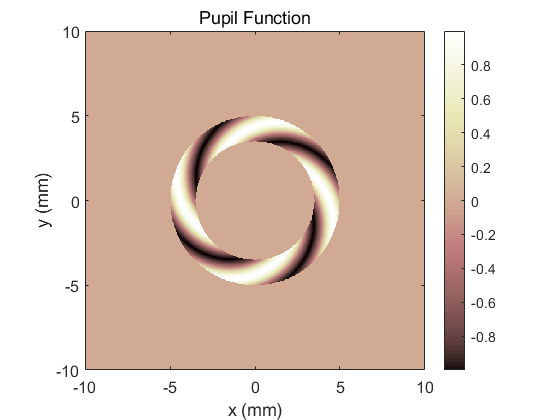

close all;
clear; clc;

% parameters
lambda = 0.0005;       % mm, in vacuum
k = 2*pi/lambda;       % vacuum wavenumber

a = 5;                 % mm, pupil size
r1 = 2.2; r2 = 3.5;    % mm, pupil range (rho : Cylindrical Coordinate)
f = 100;               % mm, focal length
zs = [-0.8 0 0.8];     % mm, defucus
m = 4;                 % integer, topological charge

% coordinate
xL = a*15;             % mm, half limit in x
yL = a*15;             % mm, half limit in y
Nx = 1024*4;
Ny = 1024*4;
x = linspace(-xL,xL,Nx);  % 1D vector
y = linspace(-yL,yL,Ny);  % 1D vector

[x2, y2] = meshgrid(x,y);
[theta, rho] = cart2pol(x2,y2); % Cartesian Coord. -> Cylindrical Coord.

% Pupil
Phase = mod(m*theta + 4*pi*rho./a, 2*pi);
Pupil = zeros(size(Phase));
temp_value = exp(-1i*Phase);
Pupil(rho<a) = temp_value(rho<a);
Pupil(rho<r2) = 0;
Pupil(rho<r1) = exp(1i*2*pi);

figure; imagesc(x, y, imag(Pupil)); axis image; colormap('pink'); colorbar;
set(gca,'YDir','normal','FontSize',9);xlim([-10 10]);ylim([-10 10]);
xlabel('x (mm)');ylabel('y (mm)'); set(gca,'fontsize',12);
title('Pupil Function');

@ z value :  -0.8

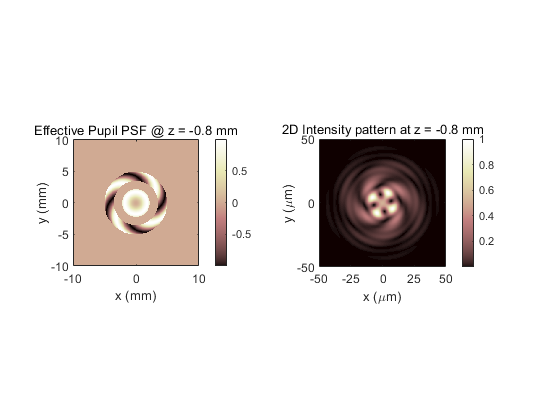

@ z value :   0.0

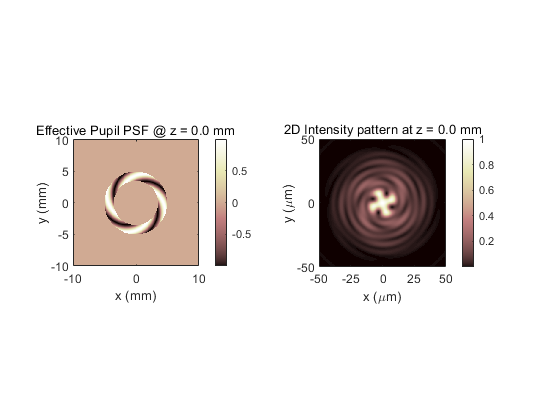

@ z value :   0.8

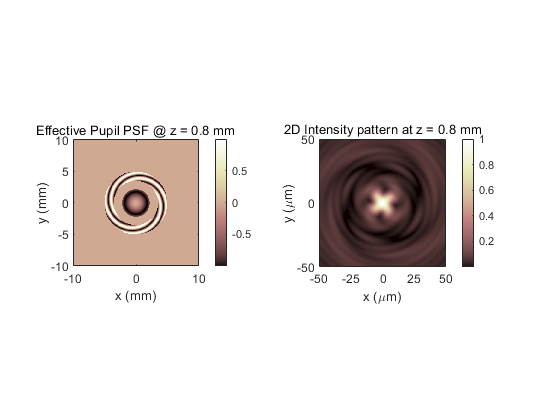


for cnt = 1: length(zs)
    fprintf('@ z value : %5.1f', zs(cnt))
    
    % effective Pupil
    eff_pupil = Pupil.*exp(-1i*k*zs(cnt)/(2*f^2).*rho.^2);
    
    % Fast Fourier Transform
    fft = fftshift(fft2(eff_pupil));
    I_fft = abs(fft).^2;
    nI_fft = I_fft/max(I_fft(:)); % normalized
    
    % Coordinates (f -> x)
    fx = 1/diff(x(1:2))*linspace(-Nx/2,Nx/2-1,Nx)/Nx;
    fy = 1/diff(y(1:2))*linspace(-Ny/2,Ny/2-1,Nx)/Ny;
    x2 = fx*(lambda*(f+zs(cnt)));
    y2 = fy*(lambda*(f+zs(cnt)));

    xLdisp = 50;   % micron
    yLdisp = 50;   % micron
    
    % Plotting
    figure;
    subplot(1,2,1); imagesc(x,y,imag(eff_pupil)); axis image; colormap pink; colorbar;
    set(gca,'YDir','normal','FontSize',9);xlim([-10 10]);ylim([-10 10]);
    xlabel('x (mm)');ylabel('y (mm)');
    title(['Effective Pupil PSF @ z = ',num2str(zs(cnt),'% 5.1f'),' mm']);

    subplot(1,2,2); imagesc(x2*1000,y2*1000,nI_fft); axis image; colormap pink; colorbar;
    xlim([-xLdisp xLdisp]);ylim([-yLdisp yLdisp]);set(gca,'fontsize',9);
    set(gca,'XTick',-xLdisp:25:xLdisp,'YTick',-yLdisp:50:yLdisp);
    set(gca,'YDir','normal');xlabel('x (\mum)');ylabel('y (\mum)');
    title(['2D Intensity pattern at z = ',num2str(zs(cnt),'% 5.1f'),' mm']);

end

Topological charge m 값을 고려한 Pupil Function을 다음과 같이 구성하였고 이를 토대로 Effective Pupil을 계산했으며

Focus 일때와 defocus 일때 2D intensity PSF pattern을 다음과 같이 plot 하였다.

## **Q3. PSF modeling**

### ◆ Polychromatic PSF

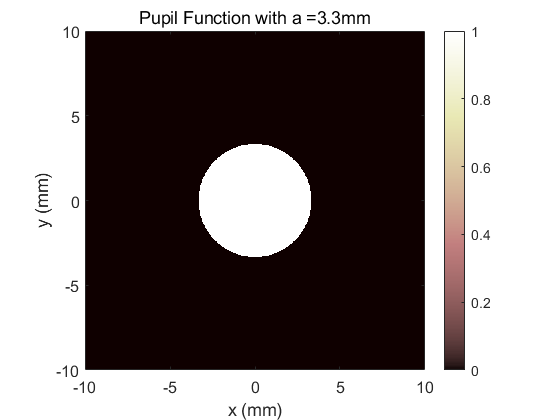

close all;
clear; clc;

% Parameters

NA = 0.5;    % Numerical Aperature
M = 20;      % Magnification
n = 1.5;     % reflective index of lens

f = 200/M;   % mm, focal length
a = NA*f/n;  % mm, Aperature size

% Coordinates
xL = a*15;             % mm, half limit in x
yL = a*15;             % mm, half limit in y
Nx = 1024*4;
Ny = 1024*4;
x = linspace(-xL,xL,Nx);  % 1D vector
y = linspace(-yL,yL,Ny);  % 1D vector

[x2, y2] = meshgrid(x,y);
[theta, rho] = cart2pol(x2,y2); % Cartesian Coord. -> Cylindrical Coord.

% Pupil Function
pupil = zeros(size(rho));
pupil(rho<a) = 1;

figure; imagesc(x, y, (pupil)); axis image; colormap('pink'); colorbar;
set(gca,'YDir','normal','FontSize',9);xlim([-10 10]);ylim([-10 10]);
xlabel('x (mm)');ylabel('y (mm)'); set(gca,'fontsize',12);
title(['Pupil Function with a =', num2str(a,'%5.1f'), 'mm']);

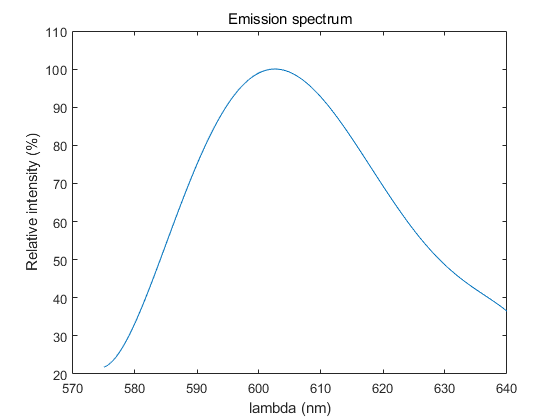


% lambda & lambda_n
lambda = 575:0.5:640; % nm, lambda = [575, 640] nm

lambda_n = zeros(size(lambda));
for i = 1:length(lambda)
    lambda_n(:,i) = (lambda(:,i) - 607.5)./19.2;    % nm
end

% Spectrum
S = zeros(size(lambda_n));
for i = 1:length(lambda_n)
    S(:,i) = (-4.3)*(lambda_n(:,i).^5)+(6.3)*(lambda_n(:,i).^4)+(22.7)*(lambda_n(:,i).^3)...
        -(41.6)*(lambda_n(:,i).^2)-(25.4)*lambda_n(:,i)+(96.6);
end
S = transpose(S);

figure; plot(lambda(:),S); xlabel('lambda (nm)'); ylabel('Relative intensity (%)');
title('Emission spectrum');

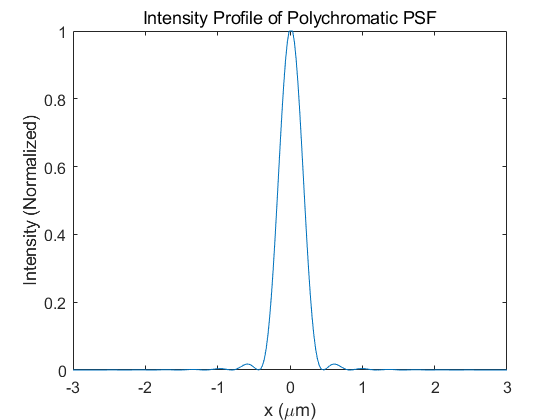


%%% Scaling lambda % lambda_n (nm -> mm)
lambda = lambda.*0.000001;        % mm
lambda_n = lambda_n.*0.000001;    % mm
S = S.*(0.01);                    % Relative Intensity (%)

% Parameters - 2
analyze_poly = zeros(length(lambda), Nx);

% Calculation of PSF using Hankel Transform
for cnt = 1:length(lambda)
    
    %  Coordinates (freq -> spatial x)
    fx = 1/diff(x(1:2))*linspace(-Nx/2,Nx/2-1,Nx)/Nx;
    fy = 1/diff(y(1:2))*linspace(-Ny/2,Ny/2-1,Nx)/Ny;
    lambda_hk = lambda(:,cnt);
    k_hk =2*pi./(lambda_hk); % wavenumber
    x3 = fx.*(lambda_hk*(f));
    y3 = fy.*(lambda_hk*(f));
    
    [x2D, y2D] = meshgrid(x3, y3);
    [theta2, rho2] = cart2pol(x2D, y2D);
    
    % Hankel Transform
    n_r2D = (k_hk*a/f).*rho2;
    apsf = 2*besselj(1,n_r2D)./(n_r2D);
    
    ipsf = abs(apsf).^2;
    n_ipsf = ipsf./max(ipsf(:));
    n_ipsf(round(Ny/2)+1, round(Nx/2)+1) = 1; % eliminate NAN value as its value is 1. [ lim(bessel(x)/x) = 0.5 ]

    % Intensity Profile @ y=0
    mat = n_ipsf(round(Ny/2)+1,:);
    analyze_poly(cnt,:) = mat; 
    
end

% Intensity attenuation: Relative Intensity (Multiply by S)
atten_I = analyze_poly.*S; 
result = sum(atten_I);
result_poly = result/max(result(:));

% Plot Polychromatic PSF intensity profile
figure; plot(x, result_poly); xlim([-3 3]); 
set(gca,'YDir','normal','FontSize',9);
xlabel('x (\mum)');ylabel('Intensity (Normalized)'); set(gca,'fontsize',12);
title('Intensity Profile of Polychromatic PSF' );

우선 Lambda에 따라 Lambda_n 값을 구해주고 이를 토대로 Spectrum의 Relative intensity값 S를 구해주었다..

그후, Hankel Transform을 이용하여 PSF를 구해주었으며 [575 640] nm 사이의 모든 PSF를 하나로 더한 뒤, 이를 앞서 구한 Relative Intensity Matrix S와 곱해준다.

이 값을 Plot하면 다음과 같다.

### ◆ FWHM of Polychromatic PSF

%% Calculation of FWHM (Polychromatic)

% Interpolate data to find FWHM
xx = -xL:0.001:xL;
yy_p = interp1(x, result_poly,xx,'spline');

new_yyp = round(yy_p,2);
zero_mat = 0.5*ones(size(new_yyp));
real_new = abs(new_yyp-zero_mat);
rlocation_p = find(real_new==min(real_new));
final_loc_p = abs(xx(rlocation_p)); 
FWHM_P = min(final_loc_p)*2; %% pick the smallest location among FWHMs found.

fprintf('FWHM for Polychromatic PSF : %5.3f', FWHM_P)

FWHM for Polychromatic PSF : 0.354

Polychromatic PSF의 FWHM을 구하면 대략 0.354$\mu m$ 정도 나오는 것을 볼 수 있다. 방법은 위와 같이 보간 후, Intensity가 0.5에 가장 가까운 값을 골라 그 중 FWHM을 가장 작게 만드는 값을 선정하였다.

### ◆ Monochromatic PSF and FWHM

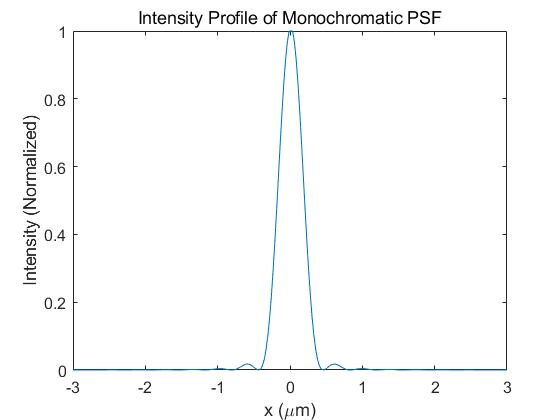

% Intensity profile of Monochromatic

lambda607 = 0.0006075;  % mm, lambda = 607.5nm

fx0 = 1/diff(x(1:2))*linspace(-Nx/2,Nx/2-1,Nx)/Nx;
fy0 = 1/diff(y(1:2))*linspace(-Ny/2,Ny/2-1,Nx)/Ny;
k_hk2 =2*pi./(lambda607);
x2p = fx0.*(lambda607*(f));
y2p = fy0.*(lambda607*(f));

[x2Dp, y2Dp] = meshgrid(x2p, y2p);
[theta3, rho3] = cart2pol(x2Dp, y2Dp);

% Hankel Transform
n_r2Dp = (k_hk2*a/f).*rho3;
apsfp = 2*besselj(1,n_r2Dp)./(n_r2Dp);

ipsfp = abs(apsfp).^2;
n_ipsfp = ipsfp./max(ipsfp(:));
n_ipsfp(round(Ny/2)+1, round(Nx/2)+1) = 1; % eliminate NAN value as its value is 1. [ lim(bessel(x)/x) = 0.5 ]

analyze_mono = n_ipsfp(round(Ny/2)+1,:);

% Normalize
result_mono = analyze_mono./max(analyze_mono(:));


% Plot Monochromatic PSF intensity profile
figure; plot(x, result_mono); xlim([-3 3]) 
set(gca,'YDir','normal','FontSize',9);
xlabel('x (\mum)');ylabel('Intensity (Normalized)'); set(gca,'fontsize',12);
title('Intensity Profile of Monochromatic PSF');



% Calculation of FWHM (Monochromatic)

% Interpolate data to find FWHM
xx = -xL:0.001:xL;
yy_mono = interp1(x, result_mono,xx,'spline');

new_yy_mono = round(yy_mono,2);
zero_mat_mono = 0.5*ones(size(new_yy_mono));
real_new_mono = abs(new_yy_mono-zero_mat_mono);
rlocation_mono = find(real_new_mono==min(real_new_mono));
final_loc_mono = abs(xx(rlocation_mono)); 
FWHM_M = min(final_loc_mono)*2; %% pick the smallest location among FWHMs found.

fprintf('FWHM for Monochromatic PSF : %5.3f', FWHM_M)

FWHM for Monochromatic PSF : 0.354

fprintf('FWHM_M - FWHM_P : %5.3f', abs(FWHM_M-FWHM_P))

FWHM_M - FWHM_P : 0.000

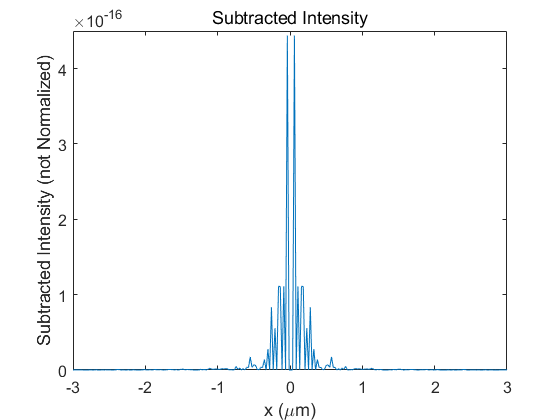


Sub = abs(result_poly-result_mono);
s
figure; plot(x, Sub); xlim([-3 3]) 
set(gca,'YDir','normal','FontSize',9);
xlabel('x (\mum)');ylabel('Subtracted Intensity (not Normalized)'); 
set(gca,'fontsize',12);
title('Subtracted Intensity');


Sub

Sub = 	1.0e+-15 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Monochromatic PSF를 구하면 다음과 같다. 여기서의 FWHM을 구하면 0.354$\mu m$가 나오는데 이는 위의 Polychromatic PSF의 FWHM 값과 동일하다. PSF의 개형도 보면 거의 비슷한 것을 확인할 수 있다.

이 두 PSF의 차이를 구해보면 아주 미세하지만 차이가 존재했는데 그 차이의 개형은 다음과 같다.

또한 비교를 위해 두 결과의 차이를 나타내는 1D Matrix를 추가로 display 했다.

위의 결과를 통해 주어진 spectrum에서 Polychromatic과 Quasi-monochromatic assumption을 이용한 Monochromatic은 차이가 거의 없음을 알 수 있으며 Assumption에 따른 PSF의 FWHM과 Polychromatic의 PSF FWHM이 거의 동일하다는 것을 확인할 수 있다.

따라서 어떤 한 Emission이 polychromatic 할 때, 이 emission의 Relative intensity를 통해 peak lambda를 찾음으로써 Monochromatic lambda를 추정할 수 있고, 이 특정 lambda 값의 PSF를 측정한다면 해당 Emission의 PSF를 추정할 수 있음을 알 수 있다.